# MXB201 Solutions 1

## Theory

### Prove, or provide a counterexample

T1.  It is not possible for a linear system of equations $Ax = b$ to have exactly two solutions.

**Proof: Suppose **$Ax_1 = b$** and **$Ax_2 = b$**.  Then **$y = x_1 - x_2$** satisfies **$Ay = A(x_1 - x_2) = Ax_1 - Ax_2 = b - b = 0$**.  So **$y$** belongs to nullspace(**$A$**).  Hence there are infintely many more possible solutions we can build from **$x_1$** and **$x_2$**.  e.g. **$x = x_1 + t (x_1 - x_2)$** for any **$t$**.**

T2.  If a square linear system $Ax = b$ has at least one solution, then $\textrm{nullity}(A) = 0$.

**False.  Any system whose solution has free variables has nullity(A) > 0.  There are several in this worksheet.**

T3.  The column space of the RREF of a matrix $A$ is the same as the column space of $A$.

**False.  Even a single column shows this to be untrue.**

A = sym([1;1]), R = rref(A)

$$A = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

$$R = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

**The respective column spaces are the spans of these vectors, and are clearly not the same.**

T4.  If two square matrices have the same row space as each other, then they have the same column space as each other.

**False.  Consider A and its RREF.  These have the same row space, but as we just saw in T3, a different column space.**

T5.  If a vector $v$ is orthogonal to all vectors in a basis for some space $W$, then $v$ is orthogonal to every vector in $W$.

**Proof: Every vector **$w$** in **$W$** can be written as **$w = c_1 w_1 + \ldots c_n w_n$**, where **$\{w_1, \ldots, w_n\}$** is the basis for **$W$**.  If **$v \cdot w_j = 0$** for **$j = 1, \ldots n$** then**

$v \cdot w = v \cdot (c_1 w_1 + \ldots c_n w_n) = c_1 v \cdot w_1 + \ldots c_n v \cdot w_n = 0 + \ldots 0 = 0$**.**

T6.  If all vectors in a basis for some space $V$ are orthogonal to all vectors in a basis for some space $W$, then every vector in $V$ is orthogonal to every vector in $W$.

**Proof: Apply the same reasoning as for T5.  Express the vectors in terms of their respective bases, and expand the dot product.  All dot products of basis vectors are zero, so the result is zero.**

## Practice

P1.  Find bases for the row space, column space and null space of the following matrices.  If you want/need the practice with row operations, start from the matrix $A$ and derive the RREF.  Otherwise, use the provided RREF $R$.  Do the rest of the working yourself.  You can check your answers at the end using MATLAB's `colspace` and `null` commands.

A_i = sym([3 1 -3 ; 3 2 0 ; 2 1 -1]), R_i = rref(A_i)

$$A\_i = \left(\begin{array}{ccc} 3 & 1 & -3\\ 3 & 2 & 0\\ 2 & 1 & -1 \end{array}\right)$$

$$R\_i = \left(\begin{array}{ccc} 1 & 0 & -2\\ 0 & 1 & 3\\ 0 & 0 & 0 \end{array}\right)$$

A_ii = sym([0 2 2 -3 ; 0 1 2 -3 ; 0 3 2 -3]), R_ii = rref(A_ii)

$$A\_ii = \left(\begin{array}{cccc} 0 & 2 & 2 & -3\\ 0 & 1 & 2 & -3\\ 0 & 3 & 2 & -3 \end{array}\right)$$

$$R\_ii = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -\frac{3}{2}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

A_iii = sym([-7 1 -6 -2 ; 0 -1 -1 3 ; 1 0 1 -1 ; 1 -1 0 2 ; 3 -2 1 0]), R_iii = rref(A_iii)

$$A\_iii = \left(\begin{array}{cccc} -7 & 1 & -6 & -2\\ 0 & -1 & -1 & 3\\ 1 & 0 & 1 & -1\\ 1 & -1 & 0 & 2\\ 3 & -2 & 1 & 0 \end{array}\right)$$

$$R\_iii = \left(\begin{array}{cccc} 1 & 0 & 1 & 0\\ 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

**We show the solution for (iii).  Hand-written solutions for (i) and (ii) are also available.**

A = A_iii;
[m,n] = size(A)

m = 5

n = 4

[R,E,bv] = rref2(A)

$$R = \left(\begin{array}{cccc} 1 & 0 & 1 & 0\\ 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$E = \left(\begin{array}{ccccc} 0 & 0 & \frac{4}{3} & \frac{2}{3} & -\frac{1}{3}\\ 0 & 0 & 2 & 1 & -1\\ 0 & 0 & \frac{1}{3} & \frac{2}{3} & -\frac{1}{3}\\ 1 & 0 & 8 & 5 & -2\\ 0 & 1 & 1 & -1 & 0 \end{array}\right)$$

bv =      1     2     4


r = rank(R) % number of nonzero rows in R

r = 3

% Row space:
RS_basis = R(1:r, :)'

$$RS\_basis = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 1 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

% Column space:
CS_basis = A(:, bv) % using columns of A

$$CS\_basis = \left(\begin{array}{ccc} -7 & 1 & -2\\ 0 & -1 & 3\\ 1 & 0 & -1\\ 1 & -1 & 2\\ 3 & -2 & 0 \end{array}\right)$$

% Alternatively, consider a general b
b = sym('b', [m,1])

$$b = \left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3}\\ b_{4}\\ b_{5} \end{array}\right)$$

R_z = E*[A b]

$$R\_z = \left(\begin{array}{ccccc} 1 & 0 & 1 & 0 & \frac{4\,b_{3}}{3}+\frac{2\,b_{4}}{3}-\frac{b_{5}}{3}\\ 0 & 1 & 1 & 0 & 2\,b_{3}+b_{4}-b_{5}\\ 0 & 0 & 0 & 1 & \frac{b_{3}}{3}+\frac{2\,b_{4}}{3}-\frac{b_{5}}{3}\\ 0 & 0 & 0 & 0 & b_{1}+8\,b_{3}+5\,b_{4}-2\,b_{5}\\ 0 & 0 & 0 & 0 & b_{2}+b_{3}-b_{4} \end{array}\right)$$

% For consistency, we require
conditions = R_z(r+1:end,end) == zeros(m-r, 1)

$$conditions = \left(\begin{array}{c} b_{1}+8\,b_{3}+5\,b_{4}-2\,b_{5}=0\\ b_{2}+b_{3}-b_{4}=0 \end{array}\right)$$

b = subs(b, solve(conditions, b(r+1:end)))

$$b = \left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3}\\ b_{2}+b_{3}\\ \frac{b_{1}}{2}+\frac{5\,b_{2}}{2}+\frac{13\,b_{3}}{2} \end{array}\right)$$

I = eye(r);
for j = 1:r
    CS_basis2(:,j) = subs(b, b(1:r), I(:,j));
end
CS_basis2

$$CS\_basis2 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ 0 & 1 & 1\\ \frac{1}{2} & \frac{5}{2} & \frac{13}{2} \end{array}\right)$$

% Null space:
R, bv  % RREF and basic variables

$$R = \left(\begin{array}{cccc} 1 & 0 & 1 & 0\\ 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

bv =      1     2     4


fv = setdiff(1:n, bv)  % free variables

fv = 3

x = sym('x', [n,1]), t = sym('t', [n-r, 1])

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4} \end{array}\right)$$

$$t = t_{1}$$

x(fv) = t

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ t_{1}\\ x_{4} \end{array}\right)$$

for i = 1:r
    eqn = R(i,:) * x == 0
    x(bv(i)) = solve(eqn, x(bv(i)))
end

$$eqn = t_{1}+x_{1}=0$$

$$x = \left(\begin{array}{c} -t_{1}\\ x_{2}\\ t_{1}\\ x_{4} \end{array}\right)$$

$$eqn = t_{1}+x_{2}=0$$

$$x = \left(\begin{array}{c} -t_{1}\\ -t_{1}\\ t_{1}\\ x_{4} \end{array}\right)$$

$$eqn = x_{4}=0$$

$$x = \left(\begin{array}{c} -t_{1}\\ -t_{1}\\ t_{1}\\ 0 \end{array}\right)$$

I = eye(n-r)

I = 1

NS_basis = sym(zeros(n,n-r));
for j = 1:n-r
    NS_basis(:,j) = subs(x, x(fv), I(:,j))
end

$$NS\_basis = \left(\begin{array}{c} -1\\ -1\\ 1\\ 0 \end{array}\right)$$

P2.  Find the general solutions to the linear systems $Ax = b$ for matrices $A$ of question P1, with the following right hand sides $b$.

b_i = sym([-4;7;1]), Rz_i = rref([A_i b_i])

$$b\_i = \left(\begin{array}{c} -4\\ 7\\ 1 \end{array}\right)$$

$$Rz\_i = \left(\begin{array}{cccc} 1 & 0 & -2 & -5\\ 0 & 1 & 3 & 11\\ 0 & 0 & 0 & 0 \end{array}\right)$$

b_ii = sym([2;4;0]), Rz_ii = rref([A_ii b_ii])

$$b\_ii = \left(\begin{array}{c} 2\\ 4\\ 0 \end{array}\right)$$

$$Rz\_ii = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & -2\\ 0 & 0 & 1 & -\frac{3}{2} & 3\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

b_iii = sym([-7;9;-2;7;6]), Rz_iii = rref([A_iii b_iii])

$$b\_iii = \left(\begin{array}{c} -7\\ 9\\ -2\\ 7\\ 6 \end{array}\right)$$

$$Rz\_iii = \left(\begin{array}{ccccc} 1 & 0 & 1 & 0 & 0\\ 0 & 1 & 1 & 0 & -3\\ 0 & 0 & 0 & 1 & 2\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

**We show the solution for (iii).  Hand-written solutions for (i) and (ii) are also available.**

A = A_iii; b = b_iii;
[R,~,bv] = rref2([A b])

$$R = \left(\begin{array}{ccccc} 1 & 0 & 1 & 0 & 0\\ 0 & 1 & 1 & 0 & -3\\ 0 & 0 & 0 & 1 & 2\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

bv =      1     2     4


fv = setdiff(1:n, bv)  % free variables

fv = 3

x = sym('x', [n,1]), t = sym('t', [n-r, 1])

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4} \end{array}\right)$$

$$t = t_{1}$$

x(fv) = t

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ t_{1}\\ x_{4} \end{array}\right)$$

for i = 1:r
    eqn = R(i,1:end-1) * x == R(i,end)
    x(bv(i)) = solve(eqn, x(bv(i)))
end

$$eqn = t_{1}+x_{1}=0$$

$$x = \left(\begin{array}{c} -t_{1}\\ x_{2}\\ t_{1}\\ x_{4} \end{array}\right)$$

$$eqn = t_{1}+x_{2}=-3$$

$$x = \left(\begin{array}{c} -t_{1}\\ -t_{1}-3\\ t_{1}\\ x_{4} \end{array}\right)$$

$$eqn = x_{4}=2$$

$$x = \left(\begin{array}{c} -t_{1}\\ -t_{1}-3\\ t_{1}\\ 2 \end{array}\right)$$

% check solution
isequal(A*x, b)

ans = logical
   1

P3. Anton's Exercise Set 4.7

Questions 1,3,5,7,9,11,15,17, and the true-false exercises.

**Answers in the back of the book.**

P4. Anton's Exercise Set 4.8

Questions 1,3,5,7,9,15,17,19,21,27, and the true-false exercises.

**Answers in the back of the book.**

## Application

### A1. Production Cost Model

Suppose you work for a health food company which wishes to produce 1000 kilograms of a new vitamin tablet, containing 0.25% folic acid, 0.25% vitamin B-6, 12% calcium, and 2% iron.  The tablets are to be made from a mixture of six preparations (labelled $A$ through to $F$) that can be obtained from your company's distributor.  The relevant vitamin content of these six preparations is given in the following table.


$$\matrix{ \ &  \textrm{\% Folic Acid} & \textrm{\% Vitamin B-6} & \textrm{\% Calcium} & \textrm{\% Iron} & \textrm{Cost (\$ / kg)} \cr
A & 0.1 & 0.1 & 18 & 3 & 4.2 \cr
B & 0.3 & 0.0 & 9 & 3 & 3.7 \cr
C & 0.2 & 0.4 & 14 & 1 & 2.5 \cr
D & 0.1 & 0.5 & 19 & 1.2 & 5.6 \cr
E & 0.4 & 0.2 & 10 & 2 & 7.2 \cr
F & 0.2 & 0.2 & 11 & 3 & 4.5}$$


(i) Write a system of equations whose solution will provide the appropriate amount of each preparation.

(ii) Analyse and solve this system of equations.  How many solutions are possible?

(iii) Express the cost in terms of a single variable.

(iv) What value of the variable used in (iii) gives the minimum cost?

(v) How much of each ingredient should be used to obtain the product at minimum cost?

**(i) Dump all the values given into a table.**

T = [
   0.1   0.1   18   3    4.2 
   0.3   0.0    9   3    3.7 
   0.2   0.4   14   1    2.5 
   0.1   0.5   19   1.2  5.6 
   0.4   0.2   10   2    7.2 
   0.2   0.2   11   3    4.5]

T =     0.1000    0.1000   18.0000    3.0000    4.2000
    0.3000         0    9.0000    3.0000    3.7000
    0.2000    0.4000   14.0000    1.0000    2.5000
    0.1000    0.5000   19.0000    1.2000    5.6000
    0.4000    0.2000   10.0000    2.0000    7.2000
    0.2000    0.2000   11.0000    3.0000    4.5000


**The first four equations come from getting the right amounts of folic acid, vitamin B-6, calcium, and iron.  The final equation enforces that we produce 1000 kg.**

A = sym([0.01*T(:, 1:end-1)'; ones(1,6)])

$$A = \left(\begin{array}{cccccc} \frac{1}{1000} & \frac{3}{1000} & \frac{1}{500} & \frac{1}{1000} & \frac{1}{250} & \frac{1}{500}\\ \frac{1}{1000} & 0 & \frac{1}{250} & \frac{1}{200} & \frac{1}{500} & \frac{1}{500}\\ \frac{9}{50} & \frac{9}{100} & \frac{7}{50} & \frac{19}{100} & \frac{1}{10} & \frac{11}{100}\\ \frac{3}{100} & \frac{3}{100} & \frac{1}{100} & \frac{3}{250} & \frac{1}{50} & \frac{3}{100}\\ 1 & 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

b = [0.01*[0.25; 0.25; 12; 2]; 1] * 1000

b = 	1.0e+03 *

    0.0025
    0.0025
    0.1200
    0.0200
    1.0000


**(ii)**

R_z = rref([A b])

$$R\_z = \left(\begin{array}{ccccccc} 1 & 0 & 0 & 0 & 0 & -\frac{37}{27} & -\frac{2500}{9}\\ 0 & 1 & 0 & 0 & 0 & \frac{202}{81} & \frac{19000}{27}\\ 0 & 0 & 1 & 0 & 0 & -\frac{146}{81} & -\frac{500}{27}\\ 0 & 0 & 0 & 1 & 0 & \frac{65}{27} & \frac{5000}{9}\\ 0 & 0 & 0 & 0 & 1 & -\frac{59}{81} & \frac{1000}{27} \end{array}\right)$$

**rank(A) = rank([A b]) = 5 < 6 = n.  There will be an infinite number of solutions, with 1 free variable.**

xP = A \ b

$$xP = \left(\begin{array}{c} -\frac{2500}{9}\\ \frac{19000}{27}\\ -\frac{500}{27}\\ \frac{5000}{9}\\ \frac{1000}{27}\\ 0 \end{array}\right)$$

NS = null(A)

$$NS = \left(\begin{array}{c} \frac{37}{27}\\ -\frac{202}{81}\\ \frac{146}{81}\\ -\frac{65}{27}\\ \frac{59}{81}\\ 1 \end{array}\right)$$

syms t
xG = xP + t * NS

$$xG = \left(\begin{array}{c} \frac{37\,t}{27}-\frac{2500}{9}\\ \frac{19000}{27}-\frac{202\,t}{81}\\ \frac{146\,t}{81}-\frac{500}{27}\\ \frac{5000}{9}-\frac{65\,t}{27}\\ \frac{59\,t}{81}+\frac{1000}{27}\\ t \end{array}\right)$$

**(iii) The cost function is linear with coefficients given in the final column of the table.**

cost = T(:, end)' * xG

$$cost = \frac{128750}{27}-\frac{2189\,t}{810}$$

**(iv)**

**Cost is a decreasing function of **$t$**, so to minimise cost, we want to substitute the largest possible value for our free variable **$t$**.  But we can't mix negative quantities of vitamins, so our optimal solution will be the largest **$t$** that keeps all of **$x_G$** nonnegative.**

**Those entries of **$x_G$** which are themselves decreasing functions of **$t$** provide the upper bounds on the feasible solutions.**

decreasing = NS < 0;
xG(decreasing)  % need to ensure these remain nonnegative

$$ans = \left(\begin{array}{c} \frac{19000}{27}-\frac{202\,t}{81}\\ \frac{5000}{9}-\frac{65\,t}{27} \end{array}\right)$$

**By division, we find the upper bounds for **$t$** that keep these entries nonnegative.**

upper_bounds = -xP(decreasing) ./ NS(decreasing)

$$upper\_bounds = \left(\begin{array}{c} \frac{28500}{101}\\ \frac{3000}{13} \end{array}\right)$$

**We need them *****both***** to be positive, so we take the minimum of these upper bounds.**

least_upper_bound = min(upper_bounds)

$$least\_upper\_bound = \frac{3000}{13}$$

**(v)**

**Substituting into the cost function:**

min_cost = double(subs(cost, t, least_upper_bound))

min_cost = 4.1449e+03

**This is our minimum cost, $4144.87, obtained by producing the following quantities of preparations A-F:**

double(subs(xG, t, least_upper_bound))

ans =    38.4615
  128.2051
  397.4359
         0
  205.1282
  230.7692


### A2. Balancing Chemical Equations

*For more background, read Anton's section on Balancing Chemical Equations, Section 1.9, pages 88--91.*

To balance the chemical equation


$$x_1\, CH_4 + x_2\, O_2 \to x_3\, CO_2 + x_4\, H_2O$$


we need to determine integer coefficients $x_i$ such that the number of atoms of each element (C, H, O) are equal on the left and right hand sides of the equation.

For Carbon (C), we require


$$x_1 = x_3$$


For Hydrogen (H), we require


$$4x_1 = 2x_4$$


For Oxygen (O), we require


$$2x_2 = 2x_3 + x_4$$


This is really a homogeneous linear system of equations in disguise.  Take all the unknowns to the left hand side, and we have


$$x_1 - x_3 = 0$$



$$4x_1 - 2x_4 = 0$$



$$2x_2 - 2x_3 - x_4 = 0$$


which is a homogeneous system of 3 equations in 4 unknowns.

The general solution then, is determined by finding the nullspace of the coefficient matrix.

A = sym([1 0 -1 0 ; 4 0 0 -2 ; 0 2 -2 -1])

$$A = \left(\begin{array}{cccc} 1 & 0 & -1 & 0\\ 4 & 0 & 0 & -2\\ 0 & 2 & -2 & -1 \end{array}\right)$$

x = null(A)

$$x = \left(\begin{array}{c} \frac{1}{2}\\ 1\\ \frac{1}{2}\\ 1 \end{array}\right)$$

Mathematically, *any* scalar multiple of this nullspace vector is a valid solution.  Physically, we cannot have fractions of molecules, so the smallest legitimate solution is twice this vector.

x*2

$$ans = \left(\begin{array}{c} 1\\ 2\\ 1\\ 2 \end{array}\right)$$

So, the balanced equation reads:


$$CH_4 + 2 O_2 \to CO_2 + 2H_2O$$


Complete Anton's Example 5, and Exercise Set 1.9 questions 9-12 (p. 95).  Or else choose any other chemical equations you like (look up some online!) and balance those.

**The solution process is just as shown for this example.**

### A3. Geometry

Find the parametric representation of the line at which the two planes $x + 2y - 3z = 2$ and $2x - y + z = -2$ intersect.

Check your answer visually.  You can use MATLAB's `fimplicit3` to plot the planes, and `fplot3` to plot the line, all on the same figure.  Use, say, a thick red line to make it stand out.

As usual, check the MATLAB documentation for how to use any MATLAB functions you're not familiar with.

syms x y z
plane1 = x + 2*y - 3*z == 2

$$plane1 = x+2\,y-3\,z=2$$

plane2 = 2*x - y + z == -2

$$plane2 = 2\,x-y+z=-2$$

figure
fimplicit3(plane1, 'FaceColor', 'Green')
hold on
fimplicit3(plane2, 'FaceColor', 'Blue')
[A,b] = equationsToMatrix([plane1, plane2])

$$A = \left(\begin{array}{ccc} 1 & 2 & -3\\ 2 & -1 & 1 \end{array}\right)$$

$$b = \left(\begin{array}{c} 2\\ -2 \end{array}\right)$$

[R_z,~,bv] = rref2([A b])

$$R\_z = \left(\begin{array}{cccc} 1 & 0 & -\frac{1}{5} & -\frac{2}{5}\\ 0 & 1 & -\frac{7}{5} & \frac{6}{5} \end{array}\right)$$

bv =      1     2


Xp = sym(zeros(3,1));
Xp(bv) = R_z(:,end)

$$Xp = \left(\begin{array}{c} -\frac{2}{5}\\ \frac{6}{5}\\ 0 \end{array}\right)$$

syms t;
X = Xp + t * null(A)

$$X = \left(\begin{array}{c} \frac{t}{5}-\frac{2}{5}\\ \frac{7\,t}{5}+\frac{6}{5}\\ t \end{array}\right)$$

isequal(A*X, b)  % confirmed

ans = logical
   1

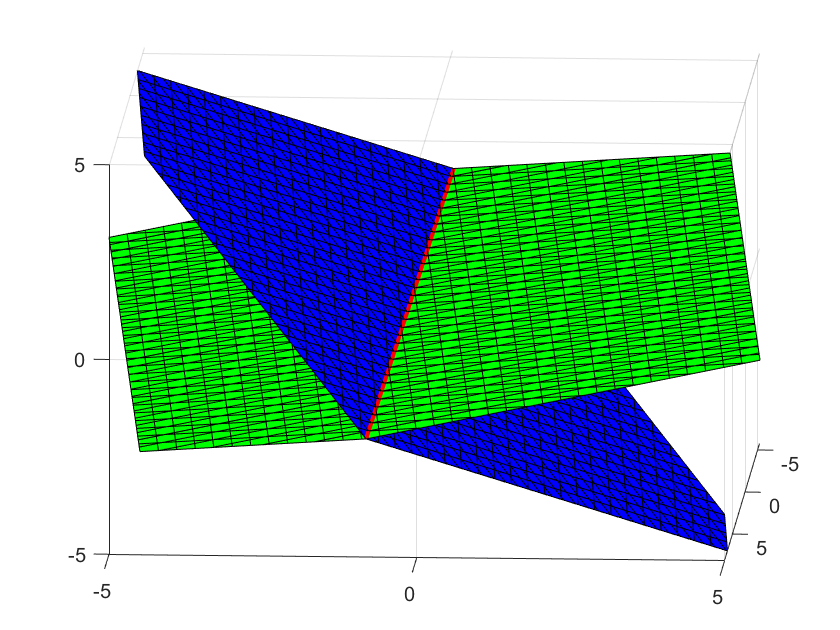

fplot3(X(1), X(2), X(3), 'r', 'Linewidth', 2)

## Exploration

### E1. Minimum Norm Solution

Lots of things to make you think in this question!  Take it slowly, refer back to the notes often.  It takes time for things to sink in, but this is a good learning exercise.

In Section 1.4 of Chapter 1, we used calculus techniques to find the minimim norm solution to $Ax=b$ for a rectangular matrix with a nonempty nullspace.  Rerun that file from Section 1.4 onwards (you can click Run to End on the toolbar) to populate MATLAB with all the variables for that example.

% Here's the set-up
m = 8;
n = 5;
A = sym([1    -1     0     1     0
         1     0     1    -3    -4
         2     2     4     0    -2
         1     0     1     2     1
         3     3     6     0    -3
         0     2     2     2     2
         0     1     1     4     4
         3    -2     1     2    -1]);
CS_basis = colspace(A);
NS_basis = null(A);
RS_basis = colspace(A');
nullityA = size(NS_basis, 2);
b = CS_basis * [3;1;4]; % just take some arbitrary linear combination
x_p = A \ b;  % particular solution to the non-homogeneous system

c = sym('c', [nullityA, 1], 'real');
x_h = NS_basis * c;  % general solution to the homogeneous system
x_nh = x_p + x_h;  % general solution to the non-homogeneous system
norm_sq = simplify(norm(x_nh)^2); % we'll minimise the squared norm since it's easier
eq_sp = gradient(norm_sq) == 0;
[c1, c2] = solve(eq_sp);
x_min_nrm = subs(x_nh, c, [c1;c2])

$$x\_min\_nrm = \left(\begin{array}{c} \frac{37}{28}\\ -\frac{45}{56}\\ \frac{29}{56}\\ \frac{7}{8}\\ -\frac{25}{56} \end{array}\right)$$

Show (in MATLAB) that the minimum norm solution we called `x_min_nrm` belongs to the row space of $A$.

rref([RS_basis x_min_nrm])

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{37}{28}\\ 0 & 1 & 0 & -\frac{45}{56}\\ 0 & 0 & 1 & \frac{7}{8}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

**This is a consistent system.  **`x_min_nrm`** is a linear combination of the row space basis vectors.**

Show (in MATLAB) that the minimum norm solution we called `x_min_nrm` is orthogonal to the null space of $A$.

NS_basis' * x_min_nrm

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

`x_min_nrm`** is orthogonal to the basis vectors of the null space, and hence to the null space itself.**

Explain (on paper) why statements 1--2 are equivalent.

**The row space and null space are orthogonal complements.**

Write down (on paper) an extended system of equations that enforces *both* that $Ax = b$ and that $x$ is orthogonal to the null space of $A$.

**We augment the equations with the additional constraints that **`NS_basis' * x`** = 0 to enforce that **$x$** is orthogonal to the null space (and hence belongs to the row space).**

M = [A; NS_basis'], B = [b; zeros(nullityA,1)]

$$M = \left(\begin{array}{ccccc} 1 & -1 & 0 & 1 & 0\\ 1 & 0 & 1 & -3 & -4\\ 2 & 2 & 4 & 0 & -2\\ 1 & 0 & 1 & 2 & 1\\ 3 & 3 & 6 & 0 & -3\\ 0 & 2 & 2 & 2 & 2\\ 0 & 1 & 1 & 4 & 4\\ 3 & -2 & 1 & 2 & -1\\ -1 & -1 & 1 & 0 & 0\\ 1 & 0 & 0 & -1 & 1 \end{array}\right)$$

$$B = \left(\begin{array}{c} 3\\ 1\\ 4\\ \frac{22}{7}\\ 6\\ \frac{2}{7}\\ \frac{10}{7}\\ \frac{58}{7}\\ 0\\ 0 \end{array}\right)$$

Explain (on paper) why this extended system of equations is guaranteed to have a unique solution.

**We know the system is consistent: we already found a solution **`x_min_nrm`**.  The rank of the matrix **$M$** is **$n$**, since we have included an addition **$n-r$** linearly independent rows (transposed null space vectors) to the existing **$r$** linearly independent rows.**

Form and solve (in MATLAB) your extended system of equations to confirm you recover `x_min_nrm`.

y = M \ B

$$y = \left(\begin{array}{c} \frac{37}{28}\\ -\frac{45}{56}\\ \frac{29}{56}\\ \frac{7}{8}\\ -\frac{25}{56} \end{array}\right)$$

isequal(y, x_min_nrm)

ans = logical
   1

Explain (on paper) why it must be that the minimum norm solution satisfies 1--2.  Hint: the solution has the minimum norm possible!

**Proved in week 3 lecture.**

Evidently, applying calculus to the problem of finding the minimum norm solution was overkill!  If we were smarter, we could have reasoned as above, and just picked the minimum norm solution we sought from the row space of $A$.  We'll revisit this idea in later chapters.  In fact, we'll see on numerous occasions how linear algebra provides elegant solutions to problems that might have appeared to require calculus in order to solve.

### E2. Trigonometric Polynomials

A trigonometric polynomial of degree $n$ is a function of the form


$$p_n(t) = \sum_{k=0}^n a_k \cos(kt) + \sum_{k=1}^n b_k \sin(kt)$$


Trigonometric polynomials are useful for approximating periodic functions, say by using interpolation.  For example, consider the function

$f(t) = \exp(\sin(t))$ on the interval $t \in [0, 2\pi]$.

f = @(t) exp(sin(t));
figure, fplot(f, [0,2*pi], 'DisplayName','f(t)')
xlabel t; legend

One can approximate this function by a trigonometric polynomial of degree $n = 2$ (say), by sampling the function $f$ at the equally spaced values $t_0,\ldots, t_4  = 0,\ 2\pi/5,\ 4\pi/5,\ 6\pi/5,\ 8\pi/5$.

Then, imposing the interpolation conditions $p_2(t_k) = f(t_k)$ for $k = 0,\ldots, 4$ generates a linear system of equations for the unknown coefficients $a_k$ and $b_k$ in the interpolant$p_2(t) = a_0 + a_1 \cos(t) + a_2 \cos(2t) + b_1 \sin(t) + b_2 \sin(2t)$.

For example, we require $p_2(t_0) = f(t_0)$, so the first equation reads:


$$a_0 + a_1 \cos(t_0) + a_2 \cos(2t_0) + b_1 \sin(t_0) + b_2 \sin(2t_0) = \exp(\sin(t_0))$$


or more simply,

$a_0 + a_1 + a_2 = 1$.

With pen and paper, write out the full $5 \times 5$ system of equations obtained (this is just to confirm you have things clear in your mind).

Then, enter the coefficient matrix and right-hand-side vector in MATLAB.  Use whatever shortcuts you find convenient to cut down on the typing required.

Solve the linear system (using backslash is fine) to obtain the required coefficients for your trigonometric polynomial.

Plot this trigonometric polynomial on the same axes as the function.  You should find your solution looks like this.

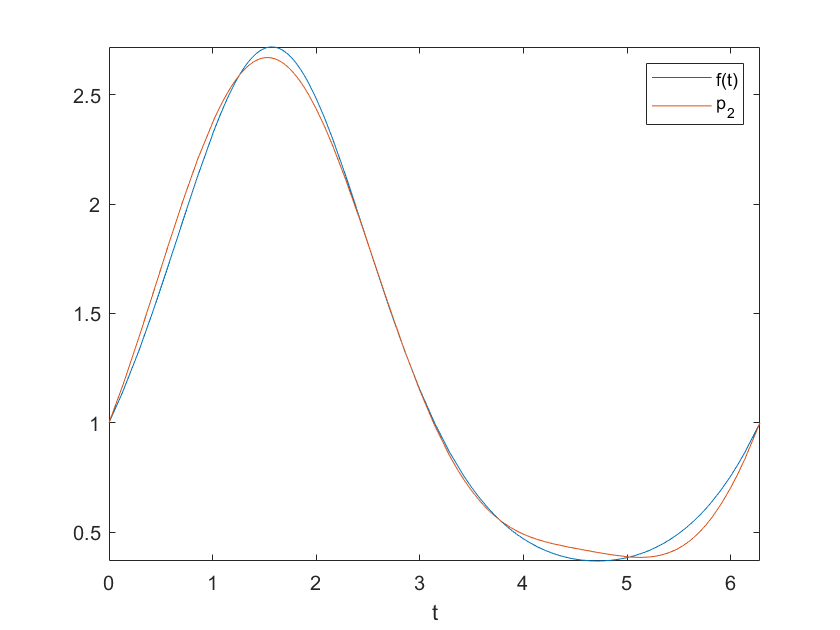

p2 = trig_interp(f, 2)

$$p2 = 0.04433365141216138\,\sin\left(2.0\,t\right)-0.2714951403205569\,\cos\left(2.0\,t\right)+0.005429263119138192\,\cos\left(t\right)+1.130318196923219\,\sin\left(t\right)+1.266065877201419$$

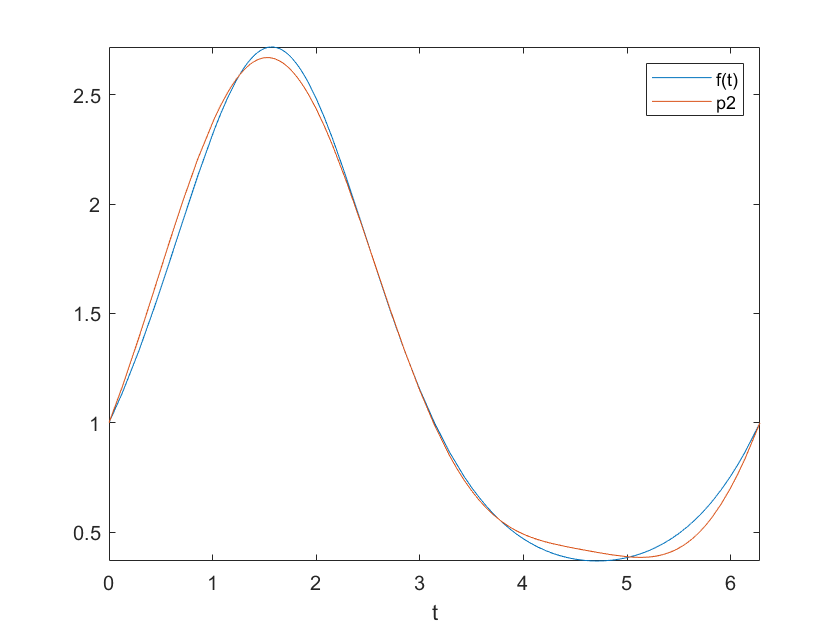

hold on
fplot(p2, [0,2*pi], 'DisplayName', 'p2')

## Software

### S1. Linear Solver

Write a MATLAB function `linear_solve` that takes as input an $m\times n$ symbolic matrix $A$ and $n \times 1$ right hand side vector $b$, and returns the solution $x$ to $Ax = b$.  It should:

- output an error message if there is no solution

- output a warning message if there are infinitely many solutions

- return the general solution (not just a particular solution) if there are infinitely many solutions

- not use MATLAB's backslash command

- use the commands `rank`, `null`, `rref2`, or whatever else seems helpful.

Test your function out on various examples to check it handles all the different cases correctly.

**See **`linear_solve.m`

### S2. Trigonometric Polynomials

Write a MATLAB program that computes the trigonometric polynomial interpolant for any $2\pi$-periodic function $f$ and any degree $n$.  Pick a few periodic functions, and have fun plotting their first few trigonometric interpolants.  How quickly do the interpolants converge to the true function?  Does it depend on how smooth the functions are?  Be sure to test out some definitely not smooth functions (like a square wave, for example).

**See **`trig_interp.m`

### S3. Application Solvers

Write MATLAB programs to solve problems A1--A3 for general inputs.

**Left as an exercise for the reader!**